## **Loading the Data**

Useing the image datastore function to add the data and assign labels accordingly

%Loading the data set
% Clear workspace
clear; close all; clc;
% Images Datapath – Please modify your path accordingly
datapath='cell_images';

% Image Datastore
imds=imageDatastore(datapath, ...
'IncludeSubfolders',true, ...
'LabelSource','foldernames');

% Determine the split up
total_split=countEachLabel(imds)

total_split = 2×2 table
       Label       Count
    ___________    _____

    Parasitized    13778
    Uninfected     13779


## Splitting of main data set into Training, Testing and validation

As per the instruction given for the project We are to split the given dataset into 80-20 for training and testing and 90-10 for validation

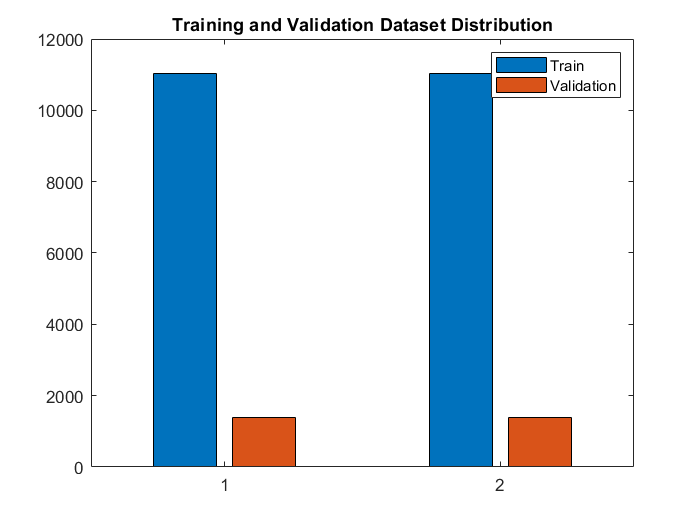

%splitting testing and validation dataset
% Split the dataset: Training and Validation
[imdsTrain,imdsTest]=splitEachLabel(imds,0.8);

[imdsTrain2,imdsValid]=splitEachLabel(imds,0.9);

% Count of Each Label in Training Dataset
train_count=countEachLabel(imdsTrain);

% Count of Each Label in Testing Dataset
valid_count=countEachLabel(imdsValid);

% Bar Graph
figure;
bar([train_count.Count,valid_count.Count]);
legend('Train','Validation')
title('Training and Validation Dataset Distribution')

## Visualizing the Dataset

We visualize by randomly picking 20 images from the data set 

This data set has 2 main classes namely:

- Parasitized

- Uninfected

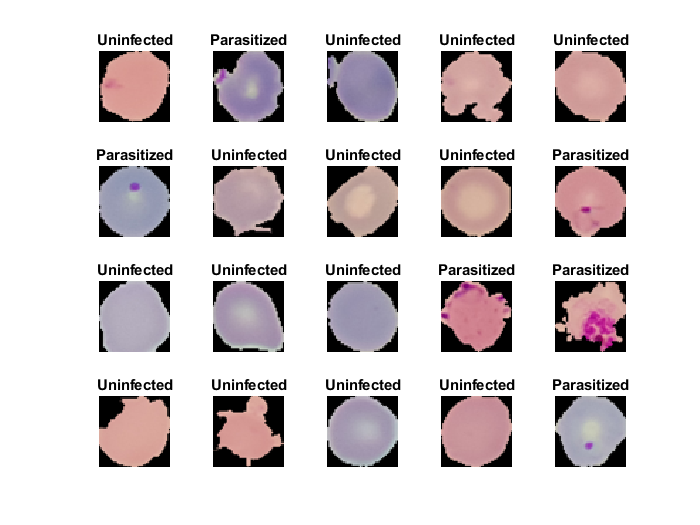

% Number of Images
num_images=length(imds.Labels);

% Visualize random 20 images
perm=randperm(num_images,20);
figure;
for idx=1:20

 subplot(4,5,idx);
 imshow(imread(imds.Files{perm(idx)}));
 title(sprintf('%s',imds.Labels(perm(idx))))

end

## Applying the preprocessing function 

Applying the preprocessing function to a sample set of image to get an idea as to what is being done

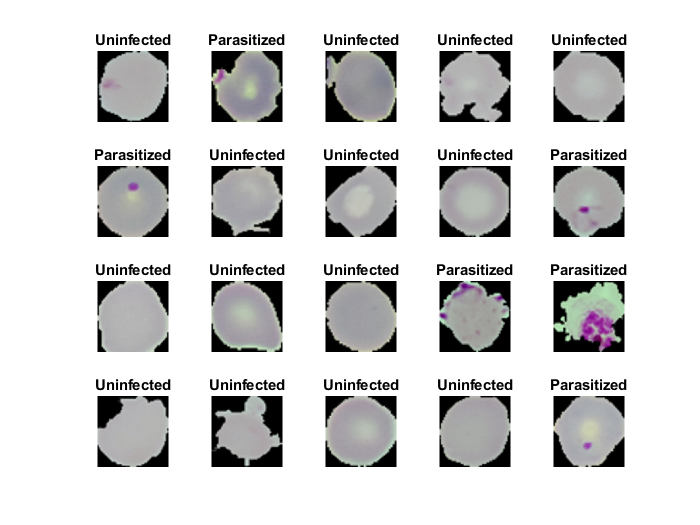

figure;

for idx=1:20
 subplot(4,5,idx);
 imshow(reformatImage(imds.Files{perm(idx)},[250 250]))
 title(sprintf('%s',imds.Labels(perm(idx))))
end


img_size = [250 250]

img_size =    250   250


## Fast CNN approach

The below code segment deals with Fast CNN appraoch built on the basis of the proposed model

**It has 7 convolution layers and 3 fully connected layers**

imdsTrain.ReadFcn=@(filename)reformatImage(filename,img_size);
imdsValid.ReadFcn=@(filename)reformatImage(filename,img_size);

% Defining the Layers
layers=[
    % Input Image Layer
    imageInputLayer([img_size,3])
    
        convolution2dLayer(5,8,'Padding','same');
        
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
        
        convolution2dLayer(5,16,'Padding','same');
       
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
        
        
        convolution2dLayer(5,32,'Padding','same');
        
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
        
        
        convolution2dLayer(5,64,'Padding','same');
       
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
    
        convolution2dLayer(5,128,'Padding','same');
        
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
        
        convolution2dLayer(5,256,'Padding','same');
       
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
    
        
        convolution2dLayer(5,512,'Padding','same');
       
        batchNormalizationLayer
        reluLayer
        maxPooling2dLayer(2,'Stride',2)
    
        
        fullyConnectedLayer(512);
        
        fullyConnectedLayer(256);
        
        fullyConnectedLayer(2);
        
        softmaxLayer
        
        classificationLayer;
    
        

    ];


% Options Parameters
options=trainingOptions('adam','MaxEpochs',4,'MiniBatchSize',64,'ValidationData',imdsValid,'ValidationFrequency',100,'Plots','training-progress','ValidationPatience',3)

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
     LearnRateScheduleSettings: [1×1 struct]
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: Inf
                     MaxEpochs: 4
                 MiniBatchSize: 64
                       Verbose: 1
              VerboseFrequency: 50
                ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
           ValidationFrequency: 100
            ValidationPatience: 3
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
                         Plots: 'training-progress'
                Sequ

Training on single GPU.


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:17 |       45.31% |       50.00% |       1.4465 |       7.9712 |          0.0010 |


|       1 |          50 |       00:00:43 |       92.19% |              |       0.2290 |              |          0.0010 |


|       1 |         100 |       00:01:21 |       98.44% |       94.56% |       0.0756 |       0.1811 |          0.0010 |


|       1 |         150 |       00:01:48 |       96.88% |              |       0.0983 |              |          0.0010 |


|       1 |         200 |       00:02:25 |       98.44% |       94.52% |       0.0952 |       0.1700 |          0.0010 |


|       1 |         250 |       00:02:53 |       92.19% |              |       0.2656 |              |          0.0010 |


|       1 |         300 |       00:03:31 |       98.44% |       95.07% |       0.0403 |       0.1627 |          0.0010 |


|       2 |         350 |       00:03:58 |       95.31% |              |       0.1598 |              |          0.0010 |


|       2 |         400 |       00:04:37 |       95.31% |       94.88% |       0.1487 |       0.1557 |          0.0010 |


|       2 |         450 |       00:05:04 |       95.31% |              |       0.1421 |              |          0.0010 |


|       2 |         500 |       00:05:43 |       98.44% |       94.81% |       0.0745 |       0.1601 |          0.0010 |


|       2 |         550 |       00:06:10 |       95.31% |              |       0.1188 |              |          0.0010 |


|       2 |         600 |       00:06:49 |       95.31% |       94.85% |       0.2134 |       0.1668 |          0.0010 |


|       2 |         650 |       00:07:16 |       93.75% |              |       0.1162 |              |          0.0010 |


|       3 |         700 |       00:07:54 |       95.31% |       94.78% |       0.1520 |       0.1525 |          0.0010 |


|       3 |         750 |       00:08:21 |       95.31% |              |       0.1466 |              |          0.0010 |


|       3 |         800 |       00:09:00 |       95.31% |       94.52% |       0.0748 |       0.1687 |          0.0010 |


|       3 |         850 |       00:09:27 |       92.19% |              |       0.1872 |              |          0.0010 |


|       3 |         900 |       00:10:06 |       90.63% |       94.38% |       0.3132 |       0.1795 |          0.0010 |


|       3 |         950 |       00:10:34 |       96.88% |              |       0.1399 |              |          0.0010 |


|       3 |        1000 |       00:11:12 |       96.88% |       94.96% |       0.1221 |       0.1496 |          0.0010 |


|       4 |        1050 |       00:11:40 |       96.88% |              |       0.1243 |              |          0.0010 |


|       4 |        1100 |       00:12:19 |       96.88% |       95.17% |       0.0957 |       0.1389 |          0.0010 |


|       4 |        1150 |       00:12:46 |       96.88% |              |       0.1088 |              |          0.0010 |


|       4 |        1200 |       00:13:25 |       95.31% |       94.78% |       0.1326 |       0.1427 |          0.0010 |


|       4 |        1250 |       00:13:53 |       93.75% |              |       0.1435 |              |          0.0010 |


|       4 |        1300 |       00:14:32 |       98.44% |       95.28% |       0.0657 |       0.1408 |          0.0010 |


|       4 |        1350 |       00:14:59 |       92.19% |              |       0.2102 |              |          0.0010 |


|       4 |        1376 |       00:15:24 |       96.88% |       94.81% |       0.0778 |       0.1439 |          0.0010 |
|======================================================================================================================|


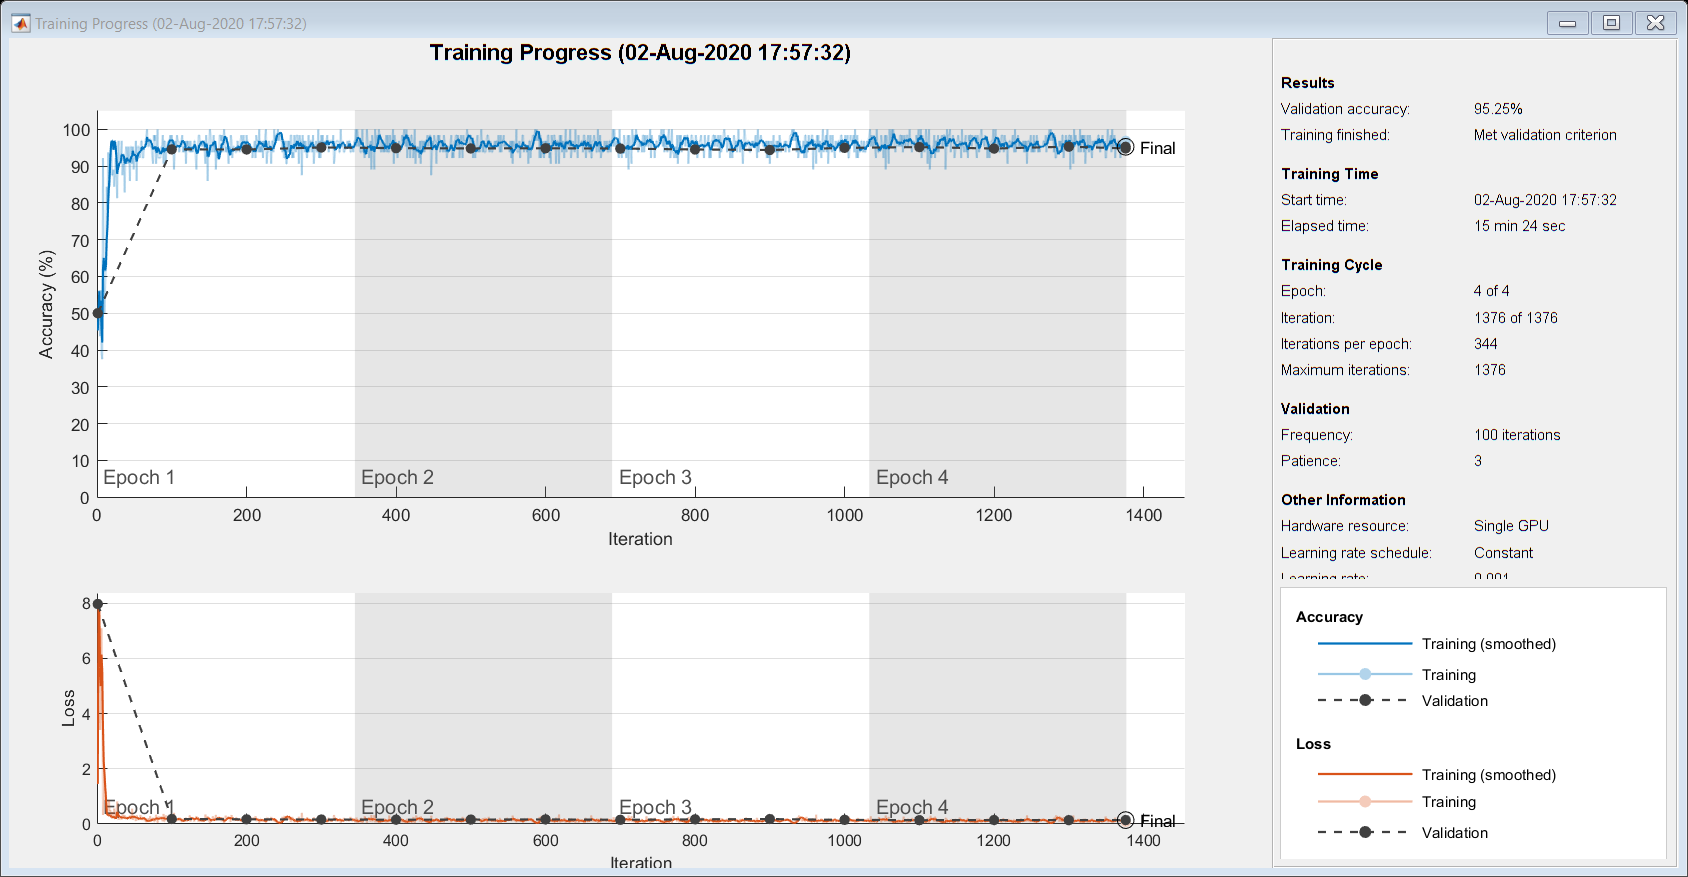

% Train the Network
net = trainNetwork(imdsTrain,layers,options);

**Testing the Model**

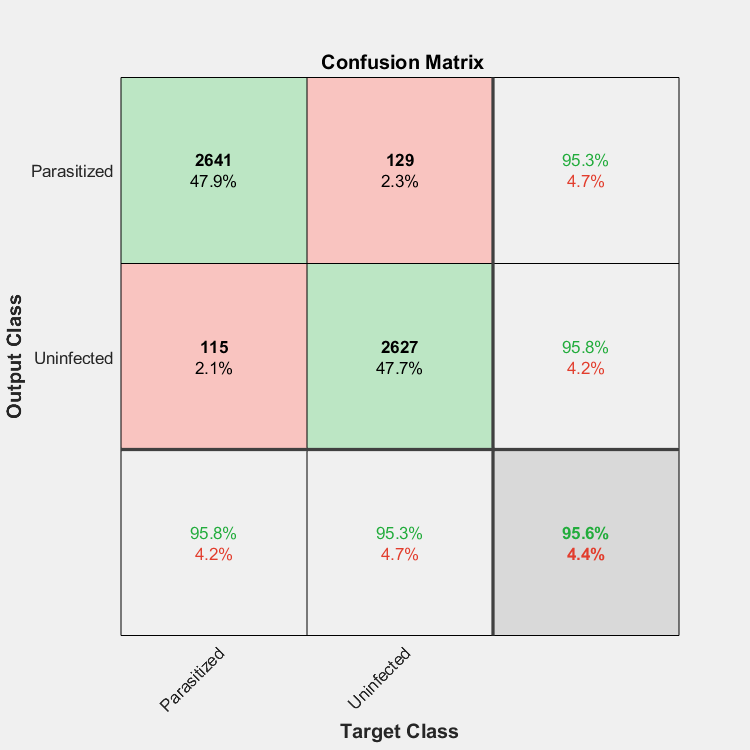

% Apply the same grayscale histogram equalization
imdsTest.ReadFcn=@(filename)reformatImage(filename,img_size);

% Predict Test Labels using MATLAB's classify command
[predicted_labels,posterior] = classify(net,imdsTest);

plotconfusion(imdsTest.Labels,predicted_labels)

## AUC - ROC Curve

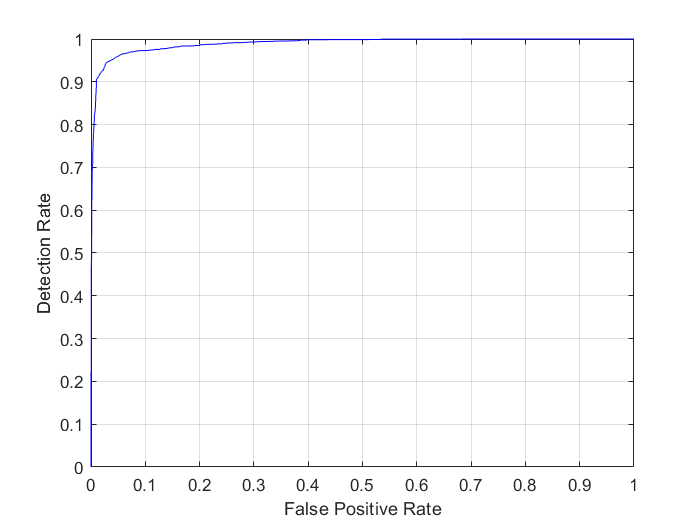

test_labels=double(nominal(imdsTest.Labels));

[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');

AUC

AUC = 0.9896

## Pre Processing Function

The preprocessing function uses Color constancy to prepare the data set for processsing

The commented segment in the middle can be used for data augmentation which rotates images randomly

function [result] = reformatImage(filename,image_size)

    I = imread(filename);
  
            rCh      = sum(sum(I(:,:,1)))/(size(I,1)*size(I,2));
            gCh      = sum(sum(I(:,:,2)))/(size(I,1)*size(I,2));
            bCh      = sum(sum(I(:,:,3)))/(size(I,1)*size(I,2));
           
            mN        = mean([rCh gCh bCh]);
          
            res(:,:,1) = (mN/rCh)*double(I(:,:,1));
            res(:,:,2) = (mN/gCh)*double(I(:,:,2));
            res(:,:,3) = (mN/bCh)*double(I(:,:,3));
            
    res = uint8(res);
    
    result = imresize(res,image_size);
    
    
    
end